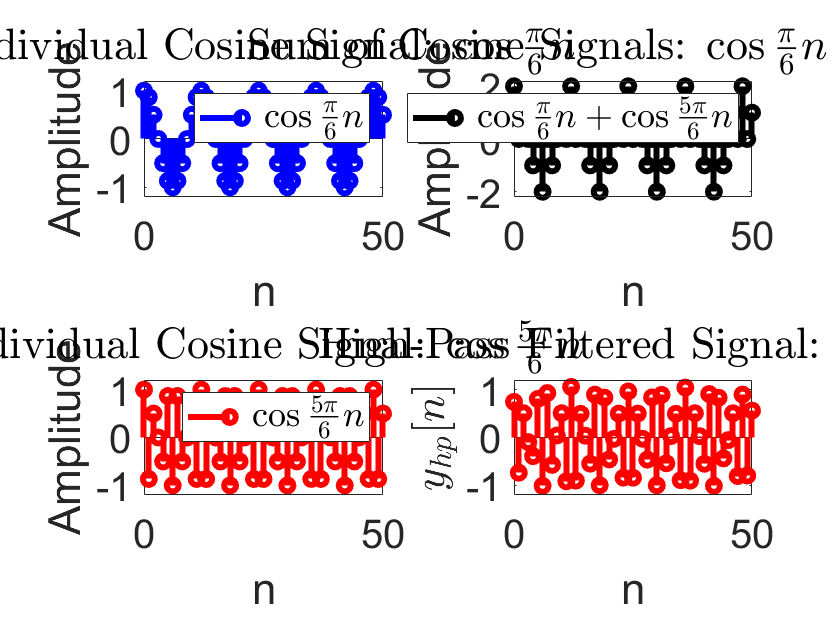

% Creating the x[n] as the sum of two sine signals
n = 0:50;
w1 = pi/6;
w2 = 5*pi/6;
x1 = cos(w1*n);
x2 = cos(w2*n);
x = x1 + x2;
w = -pi:0.001:pi;
X = dtft(n, x, w);

% Designing a High-Pass Filter in Frequency Domain
Y_hp = X;
Y_hp(abs(w) <= 3*pi/4) = 0;

% Inverse DTFT to get the time-domain signal
y_hp = idtft(w, Y_hp, n);

% Plotting the results
subplot(2,2,1)
stem(n, x1, 'blue', 'linewidth', 3);
set(gca, 'fontsize', 20);
axis([0 50 -1.2 1.2]);
xlabel('n');
ylabel('Amplitude');
legend({'$\cos \frac{\pi}{6}n$'}, 'Interpreter', 'latex');
title('Individual Cosine Signal: $\cos \frac{\pi}{6}n$', 'Interpreter', 'latex');

subplot(2,2,3)
stem(n, x2, 'red', 'linewidth', 3);
set(gca, 'fontsize', 20);
axis([0 50 -1.2 1.2]);
xlabel('n');
ylabel('Amplitude');
legend({'$\cos \frac{5\pi}{6}n$'}, 'Interpreter', 'latex');
title('Individual Cosine Signal: $\cos \frac{5\pi}{6}n$', 'Interpreter', 'latex');

subplot(2,2,2)
stem(n, x, 'black', 'linewidth', 3);
set(gca, 'fontsize', 20);
axis([0 50 -2.2 2.2]);
xlabel('n');
ylabel('Amplitude');
legend({'$\cos \frac{\pi}{6}n+\cos \frac{5\pi}{6}n$'}, 'Interpreter', 'latex');
title('Sum of Cosine Signals: $\cos \frac{\pi}{6}n+\cos \frac{5\pi}{6}n$', 'Interpreter', 'latex');

subplot(2,2,4)
stem(n, real(y_hp), 'red', 'linewidth', 3);
set(gca, 'fontsize', 20);
axis([0 50 -1.2 1.2]);
xlabel('n');
ylabel('$y_{hp}[n]$', 'Interpreter', 'latex');
title('High-Pass Filtered Signal: $y_{hp}[n]$', 'Interpreter', 'latex');